# Step 1: Basic Control Design Concepts

In this section, we will cover basic control design concepts in MATLAB and Control System Toolbox. We will construct transfer functions using linear time-invariant objects, assemble components into a feedback loop, tune controller gains, and evaluate controller performance. These steps will lay the foundation for the robust control topics covered in Step 2 and Step 3.

## Build a feedback loop

In this step, we'll work with this SISO feedback loop:

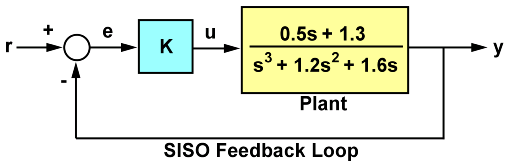

You can build components of a feedback loop with MATLAB code using [LTI objects](https://www.mathworks.com/help/control/getstart/linear-lti-models.html). For this exercise, we'll use [transfer function LTI objects](https://www.mathworks.com/help/control/ref/tf.html) to represent the plant and controller.

First, create a transfer function object for the plant:

G = tf([.5 1.3],[1 1.2  1.6 0])

G =
 
       0.5 s + 1.3
  ---------------------
  s^3 + 1.2 s^2 + 1.6 s
 
Continuous-time transfer function.



Next, we'll create a transfer function object for the controller. The controller in the diagram above has a gain of "K", but doesn't give us a value for K. Plot our plant's root locus to estimate the range of K values for which the loop is stable:

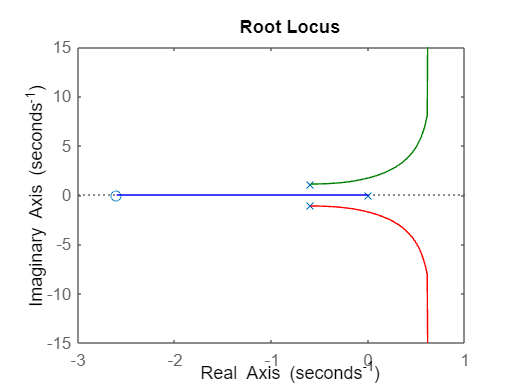

rlocus(G)

From the plot, we can see the feedback loop is stable for 0 < K < 2.7. Use the same transfer function LTI object as above to create the controller, using a K value to 1 to start.

K = 1;
C = tf(K,1)

C =
 
  1
 
Static gain.



You can connect the plant and controller objects into a feedback loop using the [feedback function](https://www.mathworks.com/help/control/ref/lti.feedback.html).

T = feedback(C*G,1)

T =
 
          0.5 s + 1.3
  ---------------------------
  s^3 + 1.2 s^2 + 2.1 s + 1.3
 
Continuous-time transfer function.



## Check stability

Stability generally means that all internal signals remain bounded. This is a standard requirement for control systems to avoid loss of control and damage to equipment. 

### Poles

For linear feedback systems, one way stability can be assessed by looking at the poles of the closed-loop transfer function. Determine the poles of our feedback loop transfer function "T" using the [poles function](https://www.mathworks.com/help/control/ref/lti.pole.html).

pole(T)

ans =   -0.2305 + 1.3062i
  -0.2305 - 1.3062i
  -0.7389 + 0.0000i


All the poles have negative real parts, therefore the feedback loop for K = 1 is stable.

### Gain and Phase Margins

Changes in the loop gain are only one aspect of robust stability. In general, imperfect plant modeling means that both gain and phase are not known exactly. Because modeling errors are most damaging near the gain crossover frequency (frequency where open-loop gain is 0dB), it also matters how much phase variation can be tolerated at this frequency.

The phase margin measures how much phase variation is needed at the gain crossover frequency to lose stability. Similarly, the gain margin measures what relative gain variation is needed at the gain crossover frequency to lose stability. Together, these two numbers give an estimate of the "safety margin" for closed-loop stability. The smaller the stability margins, the more fragile stability is.

We can determine our gain and phase margins by plotting the open-loop bode plot with the [bode function](https://www.mathworks.com/help/control/ref/lti.bode.html).

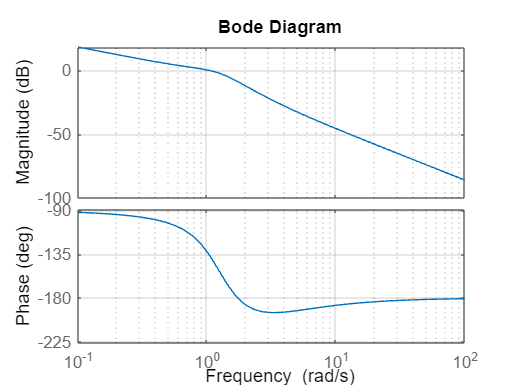

bode(C*G), grid

Then, calculate gain and phase margins for the open-loop system with the [margin function](https://www.mathworks.com/help/control/ref/lti.margin.html).

[Gm,Pm] = margin(C*G);
GmdB = 20*log10(Gm) % convert to dB

GmdB = 8.7641

Pm % degrees

Pm = 44.6703

You can also get the gain and phase margins directly from the bode plot. Run `bode(C*G), grid` from the command line. Right-click on the plot and select "Characteristics -> Minimum Stability Margins". Then, click on the blue dot markers to see the margins and other values.

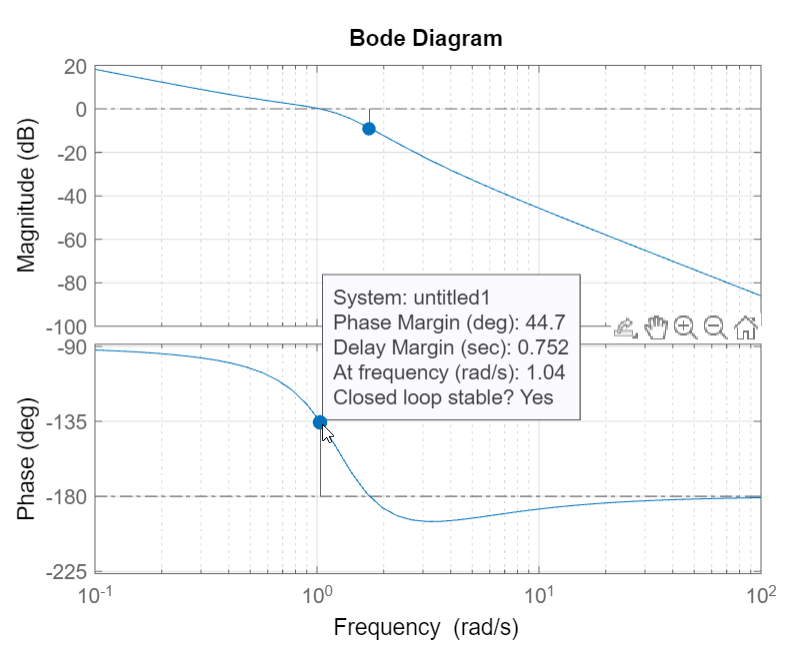

### Step Response

We can also get a sense of stability by looking at the closed-loop step response for the system. Plot the step response for "T" using the [step function](https://www.mathworks.com/help/control/ref/lti.step.html).

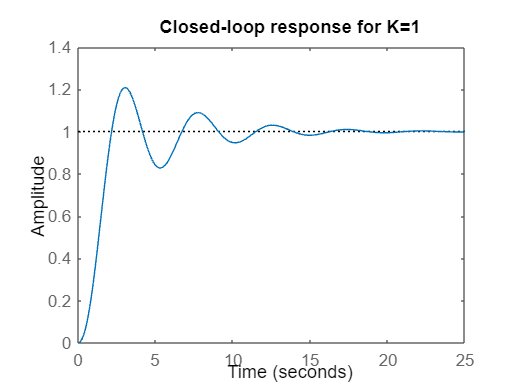

step(T), title('Closed-loop response for K=1')

When K = 1, there is ~20% overshoot and some oscillations.

Similarly to the bode plot, you can also get response characteristics directly from the step response plot. Run `step(T)` from the command line. Right click on the plot and select "Characteristics -> Peak Response". Then, click on the blue dot marker to see the values.

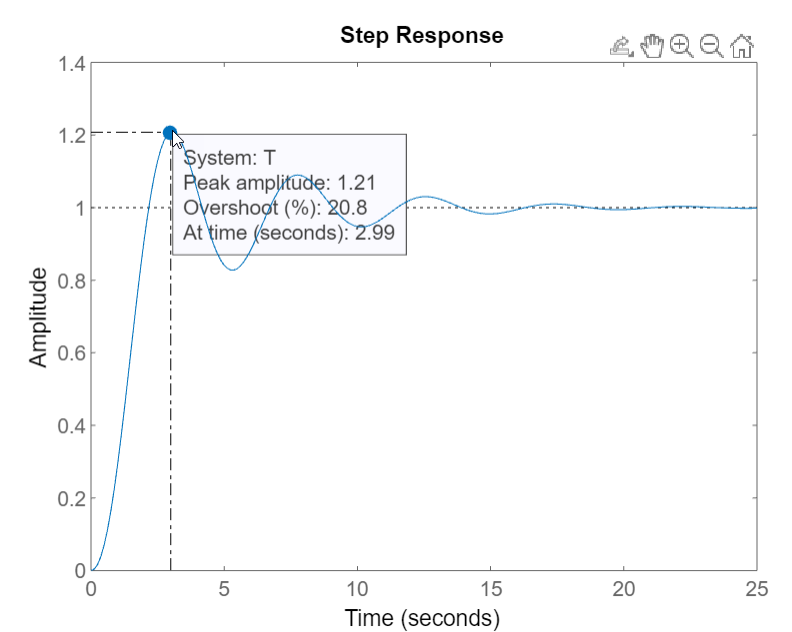

## Check stability for different controller gains

### Change the controller gain

From the root locus plot, we estimated the feedback loop would be stable for 0 < K < 2.7. Let's change the controller transfer function to use a gain of K = 2 instead of K = 1.

K = 2;
C = tf(K,1)

C =
 
  2
 
Static gain.



Connect the plant and new controller object into a feedback loop using the [feedback function](https://www.mathworks.com/help/control/ref/lti.feedback.html).

T = feedback(C*G,1)

T =
 
            s + 2.6
  ---------------------------
  s^3 + 1.2 s^2 + 2.6 s + 2.6
 
Continuous-time transfer function.



### Poles

Based on the root locus plot, we expect a gain of 2 to lead to a stable system. Let's check for stability by looking at the loop's poles: 

pole(T)

ans =   -0.0698 + 1.5643i
  -0.0698 - 1.5643i
  -1.0604 + 0.0000i


As expected, all the poles have negative real parts - the feedback loop for K = 2 is stable.

### Gain and Phase Margins

Create a bode plot:

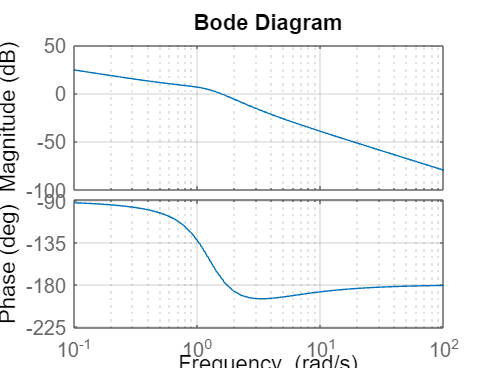

bode(C*G), grid

Calculate gain and phase margins:

[Gm,Pm] = margin(C*G);
GmdB = 20*log10(Gm) % convert to dB

GmdB = 2.7435

Pm % degrees

Pm = 8.6328

The stability margins have been reduced.

### Step Response

We can also look at a closed-loop step response. When K = 2, there are poorly damped oscillations, which is a sign of near instability.

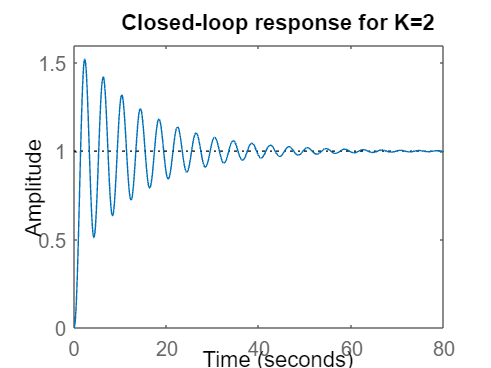

step(T), title('Closed-loop response for K=2')

## Feedback Loops with Multiple Gain or Phase Crossings

Some systems have multiple gain crossover or phase crossover frequencies, which leads to multiple gain or phase margin values. For example, consider this feedback loop:

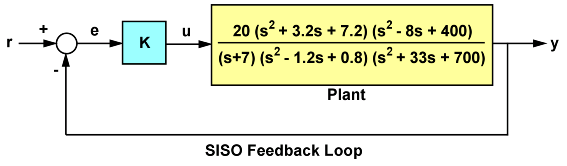

### Build a feedback loop

First, create a new transfer function object for the plant:

G2 = tf(20,[1 7]) * tf([1 3.2 7.2],[1 -1.2 0.8]) * tf([1 -8 400],[1 33 700])

G2 =
 
                                        
  20 s^4 - 96 s^3 + 7632 s^2 + 24448 s  
                                        
                                 + 57600
                                        
  --------------------------------------
                                        
  s^5 + 38.8 s^4 + 883.8 s^3 + 3815 s^2 
                                        
                         - 5135 s + 3920
                                        
 
Continuous-time transfer function.



Then, create a new transfer function object for the controller, using a K value to 1 to start.

K2 = 1;
C2 = tf(K2,1)

C2 =
 
  1
 
Static gain.



Connect the plant and controller objects into a feedback loop.

T2 = feedback(C2*G2,1)

T2 =
 
                                          
    20 s^4 - 96 s^3 + 7632 s^2 + 24448 s  
                                          
                                   + 57600
                                          
  ------------------------------------------
                                            
  s^5 + 58.8 s^4 + 787.8 s^3 + 1.145e04 s^2 
                                            
                    + 1.931e04 s + 61520    
                                            
 
Continuous-time transfer function.



### Check stability

First, plot the closed-loop reponse of the system.

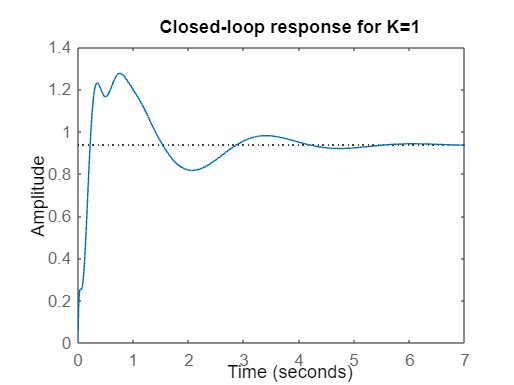

step(T2), title('Closed-loop response for K=1')

To assess how robustly stable this loop is, plot its bode response:

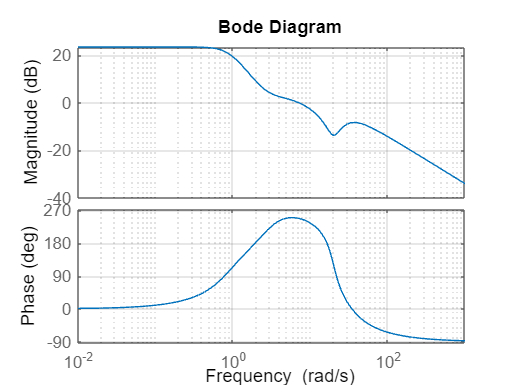

bode(C2*G2), grid

Note that there are two 180 deg phase crossings. We can calculate the gain and phase margins with the [allmargin function](https://www.mathworks.com/help/control/ref/lti.allmargin.html).

m = allmargin(G2)

m = struct with fields:
     GainMargin: [0.3408 3.3920]
    GMFrequency: [1.9421 16.4807]
    PhaseMargin: 68.1140
    PMFrequency: 7.0776
    DelayMargin: 0.1680
    DMFrequency: 7.0776
         Stable: 1



GainMargins_dB = mag2db(m.GainMargin) % convert gain margins to dB

GainMargins_dB =    -9.3510   10.6091


The two 180 deg phase crossings have corresponding gain margins of -9.35dB and +10.6dB. Negative gain margins indicate that stability is lost by decreasing the gain, while positive gain margins indicate that stability is lost by increasing the gain. We can confirm this by plotting the closed-loop step response for a plus/minus 6dB gain variation about K = 1.

Create a feedback loop where K = 2.

K2_high = 2;
C2_high = tf(K2_high,1);
T2_high = feedback(C2_high*G2,1);

Create a feedback loop where K = 0.5.

K2_low = 0.5;
C2_low = tf(K2_low,1);
T2_low = feedback(C2_low*G2,1);

Plot the step response for gains of 0.5, 1, and 2 together.

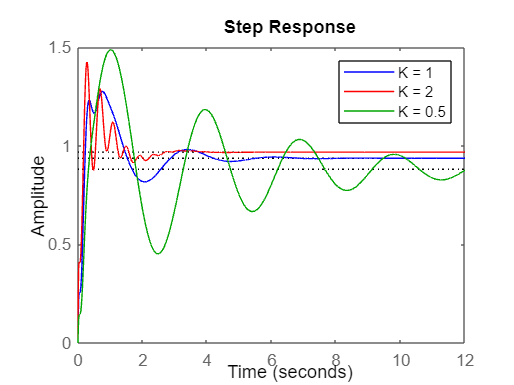

step(T2,'b',T2_high,'r',T2_low,'g',12),
legend('K = 1','K = 2','K = 0.5')

The plot shows increased oscillations for both smaller and larger gain values.

## Bonus Activity: Use Live Controls 

For the first feedback loop, we determined our system would be stable for 0 < K < 2.7. We looked at the reponse for values of K = 1 and K = 2 - but what does the reponse look like for other values of K? 

Let's control the value of K using [live controls](https://www.mathworks.com/help/matlab/matlab_prog/add-interactive-controls-to-a-live-script.html). In this example, we'll use a numeric slider. 

K = 0.8;

When we change the value of K using the slider, this section of the live script will automatically run and plot the system response.

C = tf(K,1);
T = feedback(C*G,1);

pole(T)

ans =   -0.2831 + 1.2494i
  -0.2831 - 1.2494i
  -0.6337 + 0.0000i


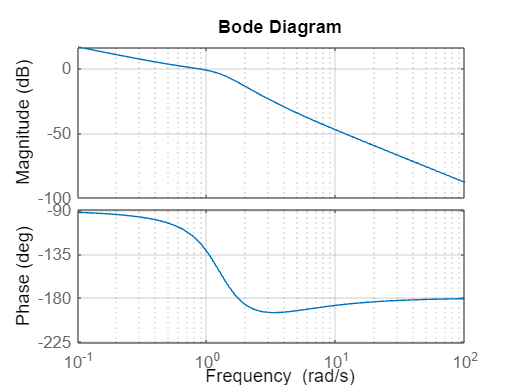

bode(C*G), grid

[Gm,Pm] = margin(C*G);
GmdB = 20*log10(Gm) % convert to dB

GmdB = 10.7023

Pm % degrees

Pm = 61.9774

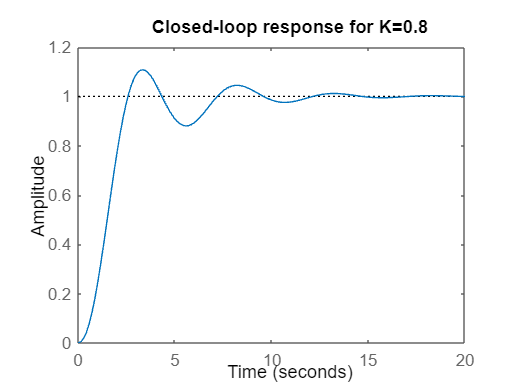

step(T), title("Closed-loop response for K=" + string(K))

## Bonus Activity: Explore Live Tasks

[Live Editor tasks](https://www.mathworks.com/help/matlab/matlab_prog/add-live-editor-tasks-to-a-live-script.html) are simple point-and-click interfaces that can be added to a live script to perform a specific set of operations. You can add tasks to live scripts to explore parameters and automatically generate code. Use tasks to reduce development time, errors, and time spent plotting.

You can explore the different live tasks using the "Task" button on the Live Editor toolstrip. Try adding a ["Tune PID Controller" live task](https://www.mathworks.com/help/control/ref/tunepidcontroller.html) to this section of the live script. Using our original plant "G", try out different types of controllers, changing performance goals, and displaying the results with different types of output plots. Also try generating code from your live task using the options in this menu:

## Bonus Activity: Explore Apps

There are [apps](https://www.mathworks.com/help/matlab/creating_guis/apps-overview.html) included in many MATLAB products, including Control System Toolbox. Let's use the [PID Tuner app](https://www.mathworks.com/help/control/ref/pidtuner-app.html) from Control System Toolbox to see if we can find a better controller for our plant "G". First, open the PID Tuner app: 

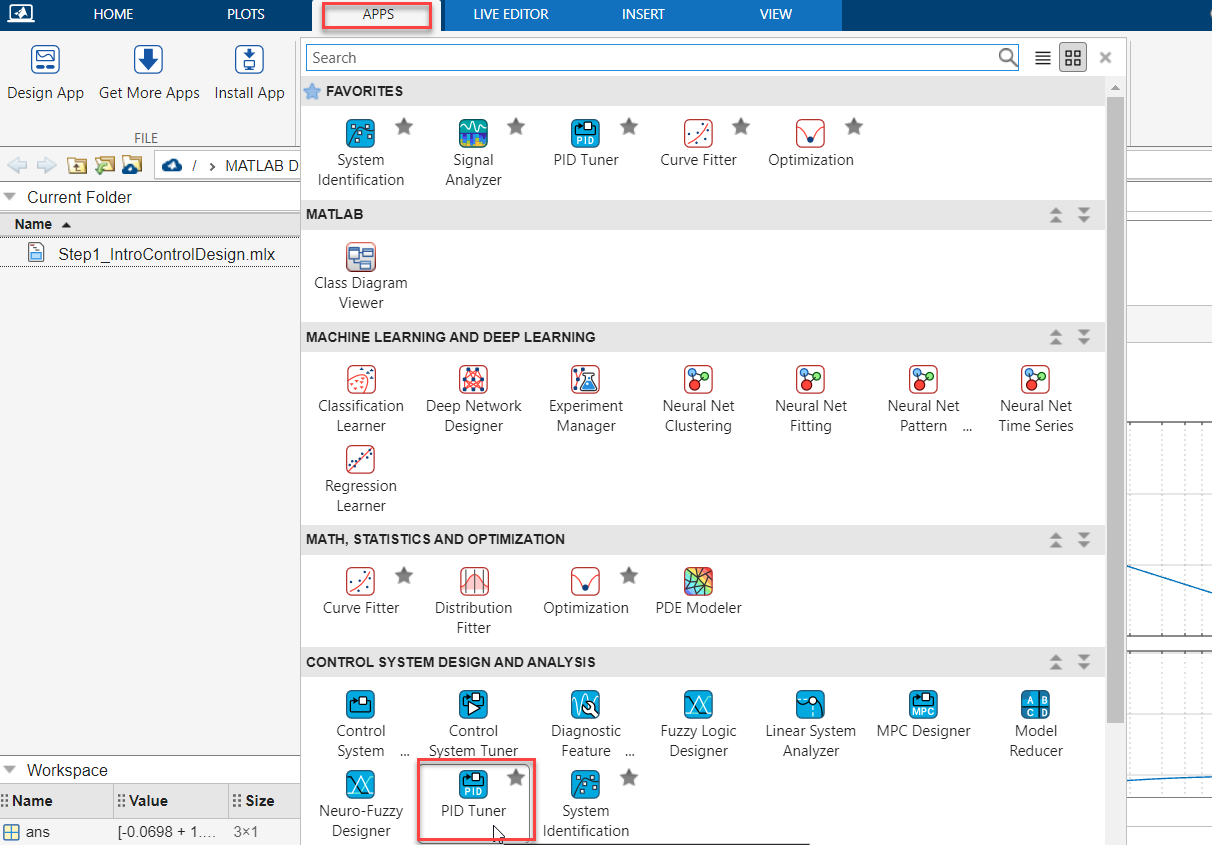

Import "G" as the plant:

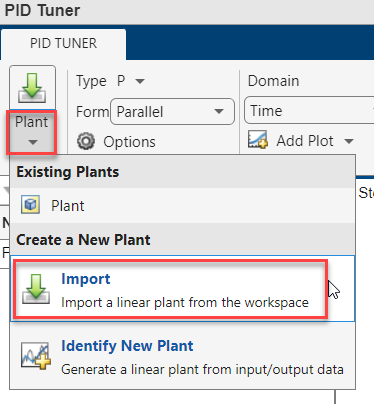

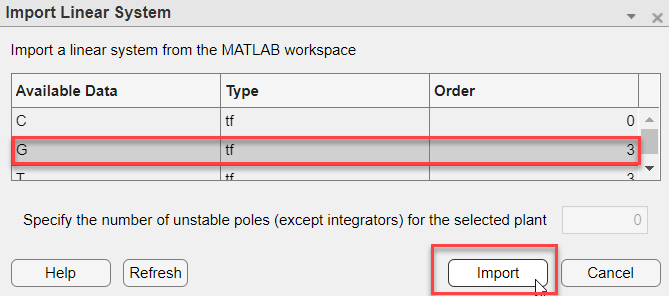

Keep the controller type as "P". The tool will automatically suggest a Kp gain that balances response time and transient behavior. Click "Show Parameters" to see the system's settling time and overshoot.

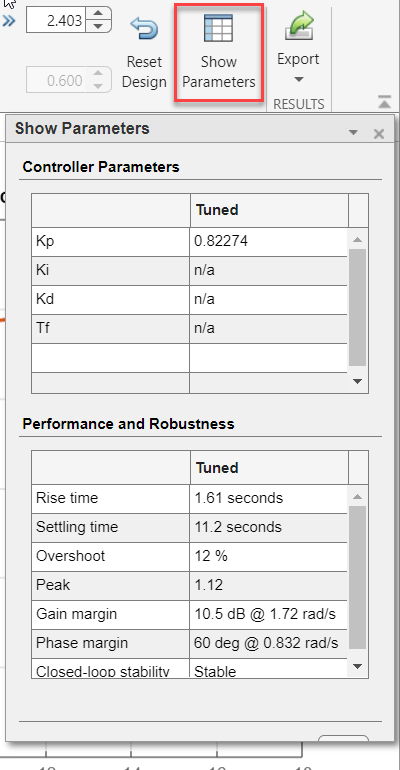

Use the slider to further tune the Kp gain. Can you find a value for Kp that minimizes settling time while also keeping overshoot less than 5%? 

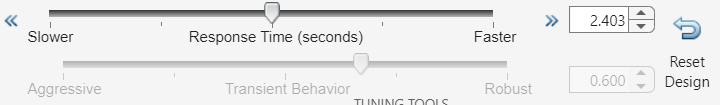

If you prefer tuning in the frequency domain: try switching the tuning domain to "frequency" and add a bode plot to visualize the response to different Kp gains.

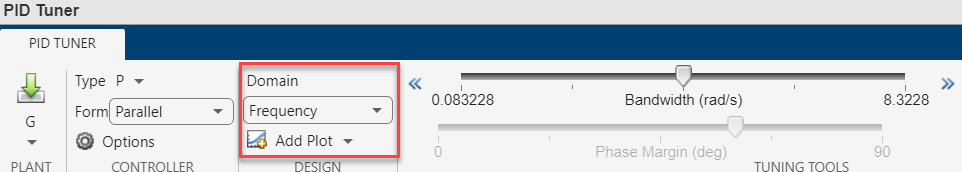

Now, change the controller type and see if you can get a quicker settling time while still keeping overshoot less than 5%. 

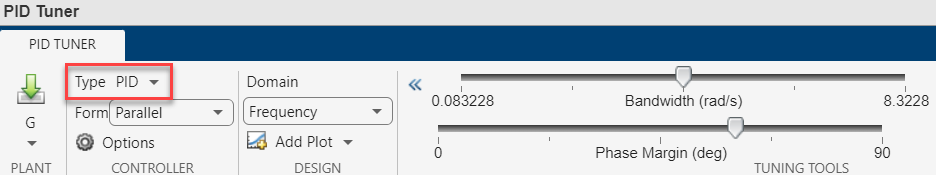

## More Examples

If you want to explore more introductory controls examples on topics like gain scheduling, trimming, linearization, and incorporating Simulink, open the appendix for Exercise 1.

open Appendix_Exercise1.mlx